# **Inbuilt Functions**

For a given ODE


$$\frac{\mathrm{dy}}{\mathrm{dx}}=3x+\frac{y}{2};y\left(0\right)=1$$


(a) Find the exact solution using MATLAB built in function

(b) Find the numerical solution using MATLAB

(c ) Plot the exact and numerical solution in the same graph

clear all;
y = dsolve('Dy=3*x+y/2', 'y(0)=1', 'x')

$$y = 13\,{\mathrm{e}}^{x/2}-6\,x-12$$

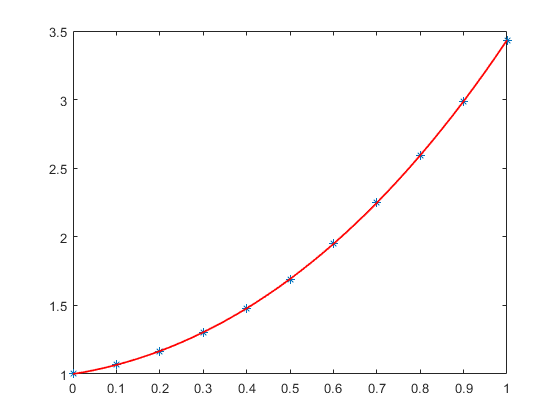

x = 0:0.1:1;

z = eval(y);
plot(x, z, '*');

hold on;

f = @(x, y) 3*x+y/2;
y0 = 1;
xspan = [0, 1];
[x, y] = ode45(f, xspan, y0);
plot(x, y, 'r', 'LineWidth', 1.3);

hold off;


$$\frac{\mathrm{dy}}{\mathrm{dx}}=2\mathrm{xy};y\left(0\right)=1$$


by taking x = [0 3]

clear all;
y = dsolve('Dy=2*x*y', 'y(0)=1', 'x')

$$y = {\mathrm{e}}^{x^{2}}$$

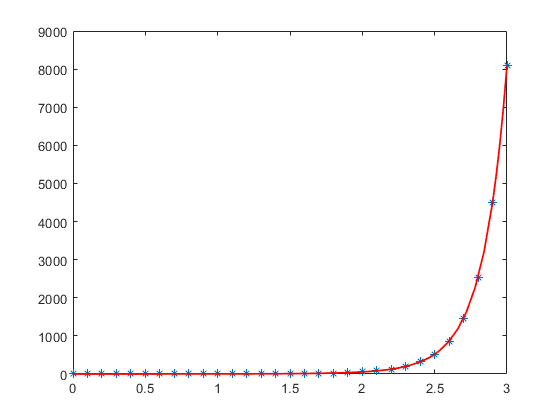

x = 0:0.1:3;

z = eval(y);
plot(x, z, '*');

hold on;

f = @(x, y) 2*x*y;
y0 = 1;
xspan = [0, 3];
[x, y] = ode45(f, xspan, y0);
plot(x, y, 'r', 'LineWidth', 1.3);
hold off;